## Analysis of the short stroke mass transfer

clear all
addpath('Spring Systems')
load('2stagesys.mat');
%setup
n_steps = 1000;
stepsize = (stage2p.S)/n_steps;
h_mass_adjustment = 0;

%state variables
Fm = stage2p.F2 %mass state

Fm = 7.8480

mass_adjustment = true%turn of height addjustment 

mass_adjustment = logical
   1


h_adjust = -5%desired adjustment output force

h_adjust = -5


r = stage2n.k/stage2p.k;
transfer_ratio = 1 / ( 1 - r)

transfer_ratio = 22.3871


%system positions
x_m = [0: -stepsize: -stage2p.S]; %position mass
x_n = x_m + stage2p.S/2; %half way of the possible stroke the equilibrium zero possition of the negative spring is located
%initial extension possitive spring is such that at x_m = 0 the system is
%in equilibrium

if mass_adjustment
   h_mass_adjustment  = -stage2p.h_adjust; %adding height addjustment
end
height_addjustment = h_adjust/transfer_ratio*1e-3 + h_mass_adjustment

height_addjustment = -0.0285

x_p = x_m - stage2p.F1/stage2p.k +  stage2p.S/2 - height_addjustment;
%The system is setum such that it's zero position is half way it's stroke


## Total energy

En = -0.5 * x_n.^2 * stage2n.k;
Ep = 0.5 * x_p.^2 * stage2p.k; 
Eg = Fm*x_m;
Etot = En + Ep + Eg; %total energy

figure()
hold on
x_axis = x_m*1e3

x_axis =          0   -0.0110   -0.0220   -0.0330   -0.0440   -0.0550   -0.0660   -0.0770   -0.0880   -0.0990   -0.1100   -0.1210   -0.1320   -0.1430   -0.1540   -0.1650   -0.1760   -0.1870   -0.1980   -0.2090   -0.2200   -0.2310   -0.2420   -0.2530   -0.2640   -0.2750   -0.2860   -0.2970   -0.3080   -0.3190   -0.3300   -0.3410   -0.3520   -0.3630   -0.3740   -0.3850   -0.3960   -0.4070   -0.4180   -0.4290   -0.4400   -0.4510   -0.4620   -0.4730   -0.4840   -0.4950   -0.5060   -0.5170   -0.5280   -0.5390


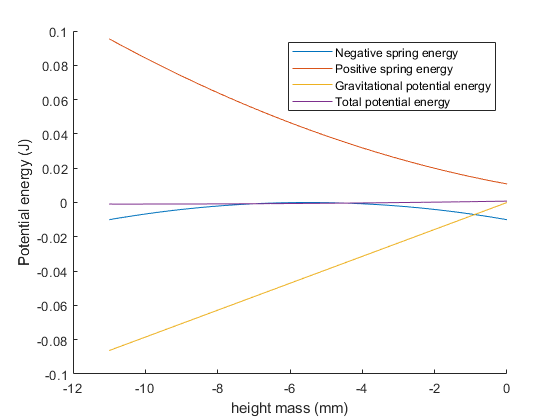

y_axismult = 1;
plot(x_axis,y_axismult * En)
plot(x_axis,y_axismult * Ep)
plot(x_axis,y_axismult * Eg)
plot(x_axis,y_axismult * Etot)
legend('Negative spring energy','Positive spring energy', ...
    'Gravitational potential energy','Total potential energy')
xlabel('height mass (mm)')
ylabel('Potential energy (J)')

## Force diagram

Fn = x_n * stage2n.k;
Fp = -x_p * stage2p.k;
Fg = Fm * ones(1,length(x_n));
Fres = - Fg + Fn + Fp;

figure()
hold on
x_axis = x_m*1e3

x_axis =          0   -0.0110   -0.0220   -0.0330   -0.0440   -0.0550   -0.0660   -0.0770   -0.0880   -0.0990   -0.1100   -0.1210   -0.1320   -0.1430   -0.1540   -0.1650   -0.1760   -0.1870   -0.1980   -0.2090   -0.2200   -0.2310   -0.2420   -0.2530   -0.2640   -0.2750   -0.2860   -0.2970   -0.3080   -0.3190   -0.3300   -0.3410   -0.3520   -0.3630   -0.3740   -0.3850   -0.3960   -0.4070   -0.4180   -0.4290   -0.4400   -0.4510   -0.4620   -0.4730   -0.4840   -0.4950   -0.5060   -0.5170   -0.5280   -0.5390


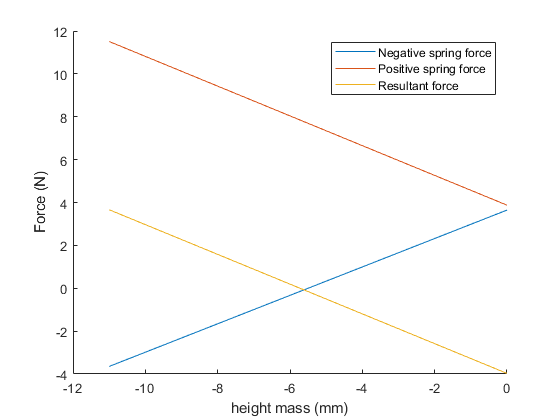

y_axismult = 1;
plot(x_axis,y_axismult * Fn)
plot(x_axis,y_axismult * Fp)
plot(x_axis,y_axismult * Fres)
legend('Negative spring force','Positive spring force','Resultant force')
xlabel('height mass (mm)')
ylabel('Force (N)')

## Total energy and resultant force

min(Fres), max(Fres)

ans = -3.9720

ans = 3.6620

figure()
x_axis = x_m*1e3

x_axis =          0   -0.0110   -0.0220   -0.0330   -0.0440   -0.0550   -0.0660   -0.0770   -0.0880   -0.0990   -0.1100   -0.1210   -0.1320   -0.1430   -0.1540   -0.1650   -0.1760   -0.1870   -0.1980   -0.2090   -0.2200   -0.2310   -0.2420   -0.2530   -0.2640   -0.2750   -0.2860   -0.2970   -0.3080   -0.3190   -0.3300   -0.3410   -0.3520   -0.3630   -0.3740   -0.3850   -0.3960   -0.4070   -0.4180   -0.4290   -0.4400   -0.4510   -0.4620   -0.4730   -0.4840   -0.4950   -0.5060   -0.5170   -0.5280   -0.5390



fig = figure();
hold on
title(('Short stroke resulting force and total potential energy'))

yyaxis left
plot(x_axis,Fres) 
ylabel('Fres') 

yyaxis right
plot(x_axis, Etot)
ylabel('Total potential energy [J]') 

xlabel('Height mass [mm]')

[val,idx] = min(Etot);
x_min = x_m(idx)*1e3

x_min = -10.5050

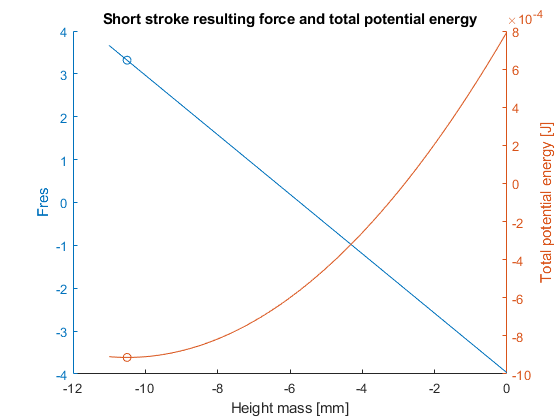

scatter(x_min,Etot(idx))
yyaxis left
scatter(x_min,Fres(idx))